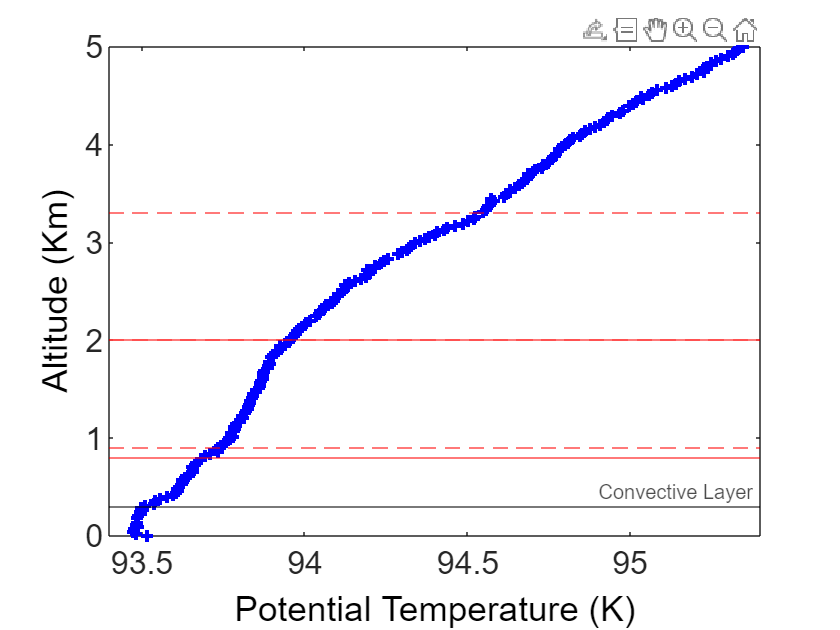

clear all; close all; clc
A5=load('HASI_L4_ATMO_PROFILE_DESCEN.TAB.txt');
A5(1,:)=[];
T4=A5(:,4).*((146720./A5(:,3)).^(0.3108));
% plot(T4,A5(:,2))
% ylim([0 3000])

for i=1:1:406   %tamaño del IS
    IS(i,1)=A5(length(T4)+1-i,2); %Altura
    IS(i,2)=T4(length(T4)+1-i);   %Temperatura Potencial
end
size=16;
plot(IS(:,2),IS(:,1)./1000,'b+','LineWidth',2)
ylim([0 5])
xlim([93.4 95.4])
hold on;
yline(.3, 'k', 'Convective Layer');
yline(.8, 'r-');
yline(2, 'r-');
yline(.9, 'r--');
yline(2, 'r--');
yline(3.3, 'r--');
xlabel('Potential Temperature (K)', 'Color', 'k','FontSize', size); 
ylabel('Altitude (Km)', 'Color', 'k','FontSize', size); 
ax = gca;  % Obtiene el objeto de los ejes actuales
ax.XAxis.FontSize = size;  % Cambia el tamaño de los números del eje X
ax.YAxis.FontSize = size;  % Cambia el tamaño de los números del eje y
hold off
print('Figura1A', '-dpng', '-r1000');

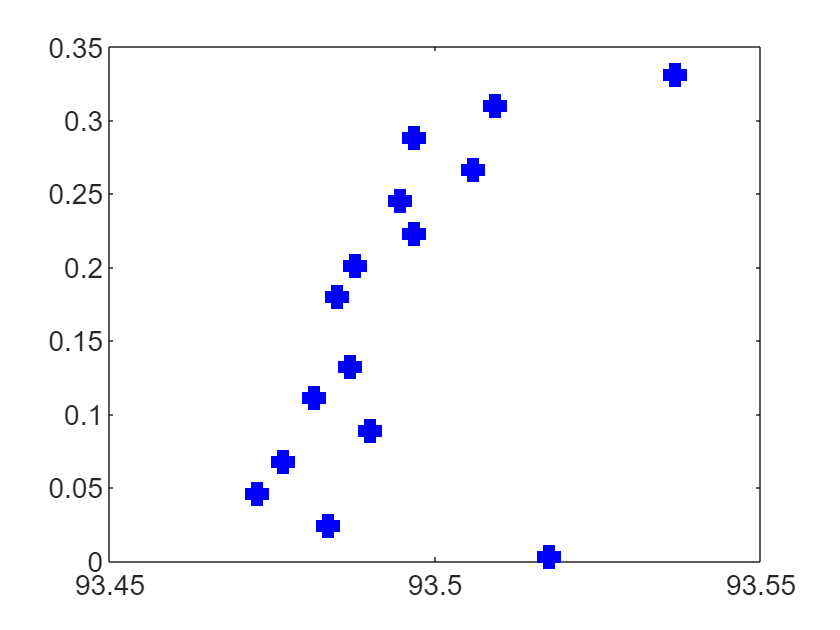

size=14;
plot(IS(:,2),IS(:,1)./1000,'b+','LineWidth',12)
ylim([0 0.35])
xlim([93.45 93.55])
ax = gca;  % Obtiene el objeto de los ejes actuales
ax.XAxis.FontSize = size;  % Cambia el tamaño de los números del eje X
ax.YAxis.FontSize = size;  % Cambia el tamaño de los números del eje y
print('Figura1A1', '-dpng', '-r1000');